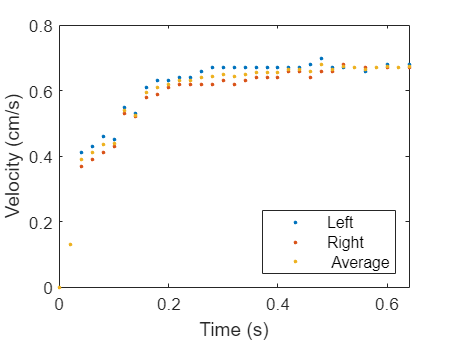

load wheel_velocities.csv
load wheel_velocities_trial_1.mat

% device = serialport("COM7", 9600);
% data = read(device, 300, "uint_");


left_velocity = wheel_velocities(:, 1);
right_velocity = wheel_velocities(:, 2);

average_velocity = mean(wheel_velocities, 2);

time = 0:0.02:0.02*(length(left_velocity) - 1);

plot(time, left_velocity,".","DisplayName", "Left"); hold on
plot(time, right_velocity,".", "DisplayName","Right"); 
plot(time, average_velocity,".", "DisplayName"," Average")
legend("Location","southeast")
hold off

xlabel("Time (s)")
ylabel("Velocity (cm/s)")



fit = fittype("k./tau.*exp(-1./tau.*x)", "dependent", {'y'}, ...
    "independent", {'x'},"coefficients", {'k', 'tau'})

fit =      General model:
     fit(k,tau,x) = k./tau.*exp(-1./tau.*x)


right_fit = fit(time', right_velocity, "fit")

right_fit = 1.0e-65 *

       NaN       NaN       NaN
         0         0         0
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
